# Geometrical Optics

## Square-Law Medium: $n^2(x,y) = n_0^2 - n_2(x^2 + y^2)$

这里是最简单的：


$$x^2(z) + y^2(z) = x_0^2$$


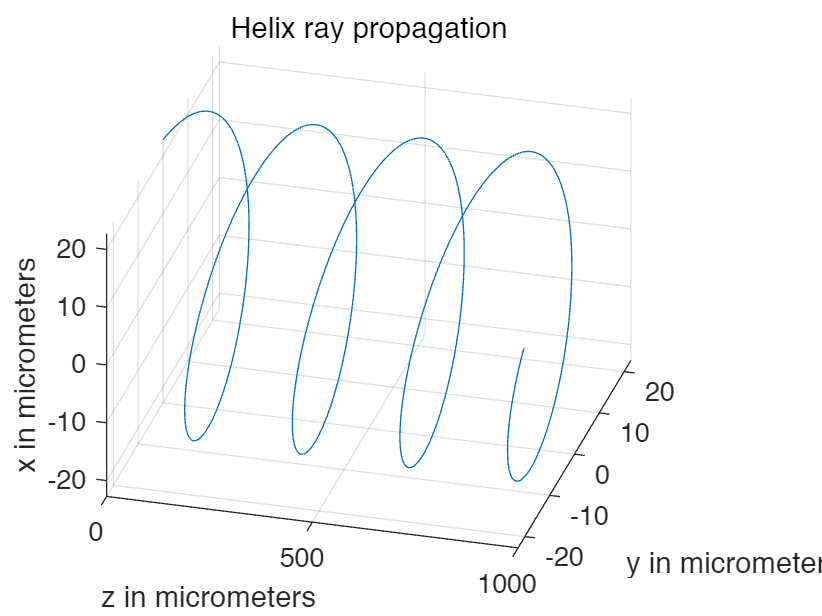

%Helix.m
%Plotting Eq. (1.3-27)

clc;
clear;
close all;

nxo = input('n(xo) = ');
n2 = input('n2 = ' ) ;
alpha = input('alpha [radian] = ' ) ;
zin = input('start point of z in micrometers = ');
zfi = input('end point of z in micrometers = ');
Beta = nxo*cos(alpha);
z=zin:(zfi-zin)/1000:zfi;
xo=Beta*tan(alpha)/(n2^0.5);
x=xo*cos((n2^0.5)*z/Beta);
y=xo*sin((n2^0.5)*z/Beta);
plot3(z,y,x);
title('Helix ray propagation');
xlabel('z in micrometers');
ylabel('y in micrometers');
zlabel('x in micrometers');
grid on;
sprintf('%f [micrometers]', xo);
view(-37.5+68, 30);

示例输入以此为：

n(xo) = 1.5

n2 = 0.001

alpha [radian] = 0.5

start point of z in micrometers = 0

end point of z in micrometers = 1000

## MATLAB code for ray traveling through a single lens, and the corresponding MATLAB output.


clc;
clear;
close all;

[detS, ri]=Ray_s([0;1] , 15, 10, 30)

detS = 1

ri =          0
   -0.5000


Type in Matlab prompt 

>> [detS, ri]=Ray_s( [0;1] , 15, 10, 30)

## Example 2 Obtaining output ray coordinates of a single lens system

clc;
clear;
close all;

[detS,ri]=Ray_d([0;1],10,10,10,10,20)

detS = 1

ri =      0
    -1


## Example 3 Finding the image location in a single lens system

clc;
clear;
close all;

[z_est, M] = Ray_z(15, 10, 0, 50, 0.1);
X = sprintf('z_est = %f, M = %f',z_est,M);
disp(X);

z_est = 30.000000, M = 0.000000


# Wave Propagation and Wave Optics

## Fresnel_Eq.m (m-file for plotting Fresnel's equations (2.2-46) and (2.2-47))

Total internal reflection 全内反射

这里考虑 $n_2 = 1.5, n_1 = 1$玻璃-空气界面。

rpa、rpe分别对应于平行偏振和垂直偏振的反射系数。

反射波的振幅与入射波的振幅相等，因此能量被完全反射，但是反射时存在相位变化，在临界角从0°变化到掠入射时的180°。结果由下面的文件绘制。

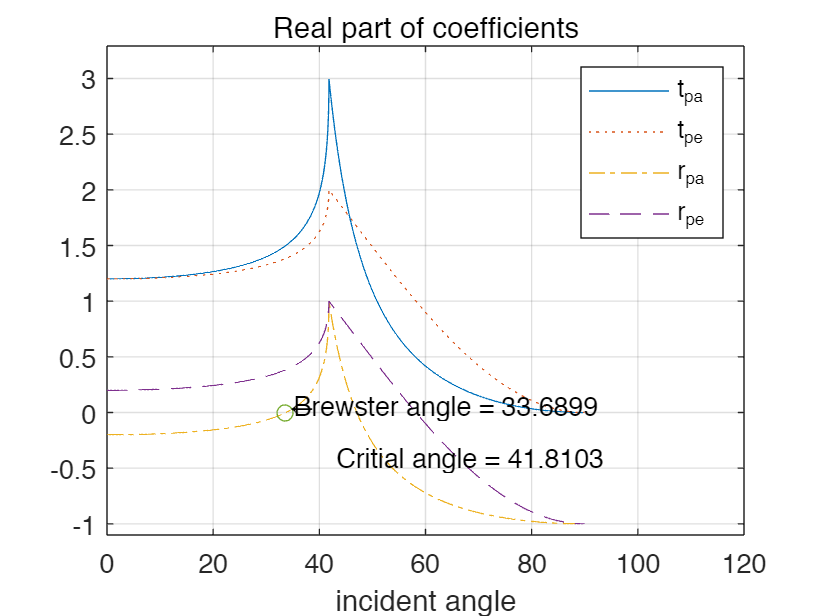

%Fresnel_Eq.m
%This m-file plots Fresnel equations (2.2-46) and (2.2-47)
clc;
clear;
close all;

n1=input('n1 =');
n2=input('n2 =');

theta_i=0:0.001:pi/2;%Incidence angle 

z=(n1/n2)*sin(theta_i);
theta_t=-j*log(j*z+(ones(size(z))-z.^2).^0.5);

r_pa=(n2*cos(theta_i)-n1*cos(theta_t))./(n2*cos(theta_i)+n1*cos(theta_t));
t_pa=(2*n1*cos(theta_i))./(n2*cos(theta_i)+n1*cos(theta_t));

r_pe=(n1*cos(theta_i)-n2*cos(theta_t))./(n1*cos(theta_i)+n2*cos(theta_t));
t_pe=(2*n1*cos(theta_i))./(n1*cos(theta_i)+n2*cos(theta_t));

[N M]=min(abs(r_pa));
theta_i=theta_i/pi* 180;
theta_cri=asin(n2/n1)* 180/pi;

figure(1);
plot(theta_i,real(t_pa),'-',theta_i,real(t_pe),':',theta_i,real(r_pa),'-.',theta_i,real(r_pe),'--', theta_i(M), 0, 'o');
m1=min([real(t_pa) real(t_pe) real(r_pa) real(r_pe)]);
M1=max([real(t_pa) real(t_pe) real(r_pa) real(r_pe)]);
legend('t_p_a','t_p_e', 'r_p_a','r_p_e');
text(theta_i(M),0.01*(M1-m1),'\leftarrow');
text(theta_i(M),0.018*(M1-m1),[' Brewster angle = ', num2str(theta_i(M))]);
if n1 >= n2
    text(theta_cri,-0.1*(M1-m1), [' Critial angle = ', num2str(theta_cri)]);
end
xlabel('incident angle');
axis([0 120 m1*1.1 M1*1.1]);
title('Real part of coefficients');
grid on;

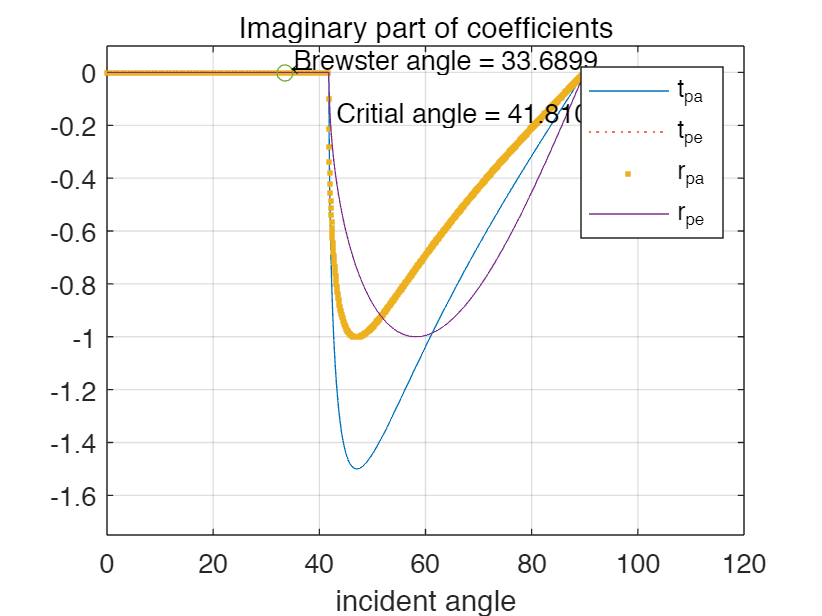


figure(2);
plot(theta_i,imag(t_pa),'-',theta_i,imag(t_pe),':',theta_i,imag(r_pa),'.',theta_i,imag(r_pe),'-', theta_i(M), 0, 'o');
m1=min([imag(t_pa) imag(t_pe) imag(r_pa) imag(r_pe)]);
M1=max([imag(t_pa) imag(t_pe) imag(r_pa) imag(r_pe)]);
m11=min([abs(imag(t_pa)) abs(imag(t_pe)) abs(imag(r_pa)) abs(imag(r_pe))]);
M11=max([abs(imag(t_pa)) abs(imag(t_pe)) abs(imag(r_pa)) abs(imag(r_pe))]);
legend('t_p_a','t_p_e', 'r_p_a','r_p_e');
text(theta_i(M),0.01*(M11-m11+0.2),'\leftarrow');
text(theta_i(M),0.03*(M11-m11+0.2),[' Brewster angle = ', num2str(theta_i(M))]);
if n1>=n2
    text(theta_cri, -0.1*(M1-m1), [' Critial angle = ', num2str(theta_cri)]);
end
xlabel('incident angle');
axis([0 120 m1*1.1-0.1 M1*1.1+0.1]);
title('Imaginary part of coefficients');
grid on;

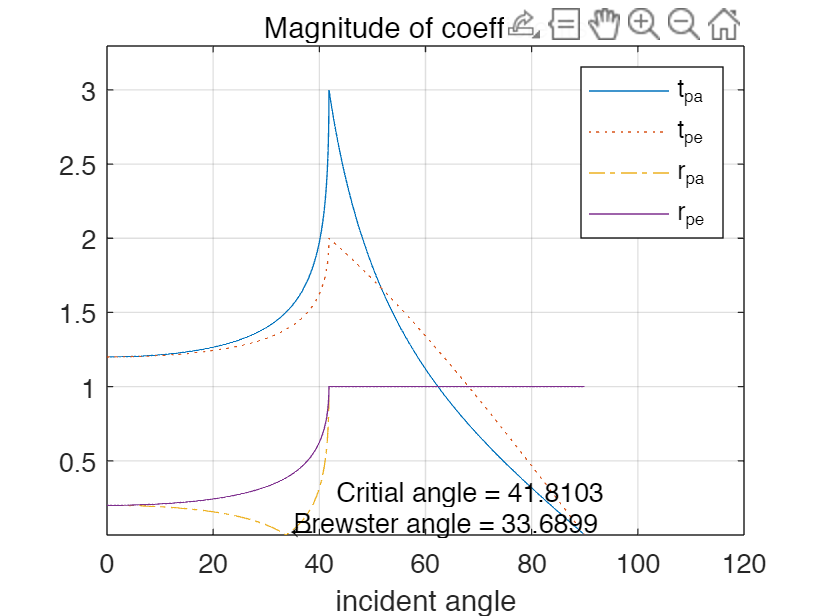


figure(3);
plot(theta_i,abs(t_pa),'-',theta_i,abs(t_pe),':',theta_i,abs(r_pa),'-.',theta_i,abs(r_pe), '',theta_i(M), 0, 'o');
m1=min([abs(t_pa) abs(t_pe) abs(r_pa) abs(r_pe)]);
M1=max([abs(t_pa) abs(t_pe) abs(r_pa) abs(r_pe)]);
legend('t_p_a','t_p_e', 'r_p_a','r_p_e');
text(theta_i(M),0.01*(M1-m1),['\leftarrow']);
text(theta_i(M),0.03*(M1-m1),[' Brewster angle = ', num2str(theta_i(M))]);
if n1>=n2
    text(theta_cri, 0.1*(M1-m1), [' Critial angle = ', num2str(theta_cri)]);
end
xlabel('incident angle');
axis([0 120 m1*1.1 M1*1.1]);
title('Magnitude of coefficients');
grid on;

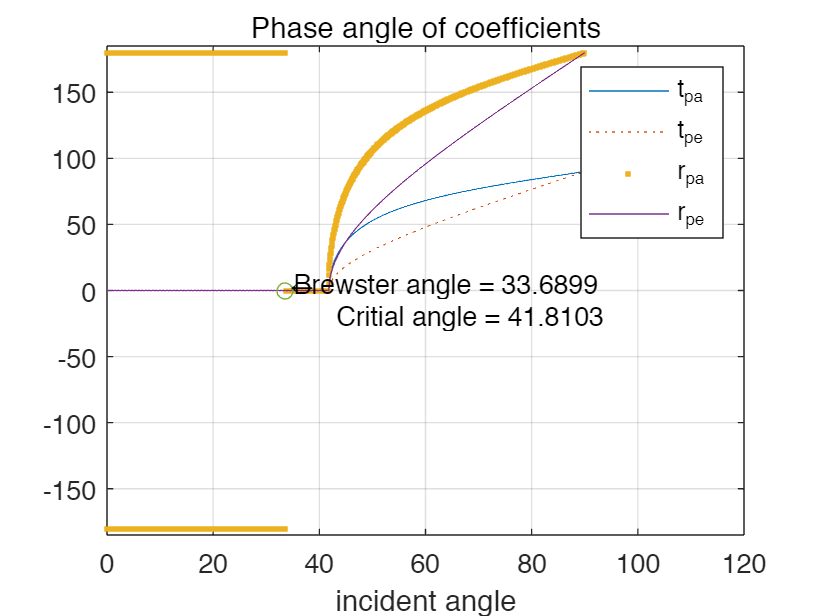


figure(4);
plot(theta_i,real(j * 180/pi*log(t_pa)),'',theta_i,real(j* 180/pi*log(t_pe)),':',theta_i,real(j * 180/pi*log(r_pa)),'.',theta_i,real(j*180/pi*log(r_pe)), '-',theta_i(M), 0, 'o');
m1=real(min([ -j*180/pi*log(r_pa) -j*180/pi*log(r_pe)]));
M1=real(max([ -j*180/pi*log(r_pa) -j*180/pi*log(r_pe)]));
legend('t_p_a','t_p_e', 'r_p_a','r_p_e');
text(theta_i(M),0.015*(M1-m1),['\leftarrow']);
text(theta_i(M),0.03*(M1-m1),[' Brewster angle = ', num2str(theta_i(M))]);
if n1>=n2
    text(theta_cri, -0.1*(M1-m1), [' Critial angle = ', num2str(theta_cri)]);
end
xlabel('incident angle');
axis([0 120 -185 185]);
title('Phase angle of coefficients');
grid on;

n1 =1.5

n2 =1

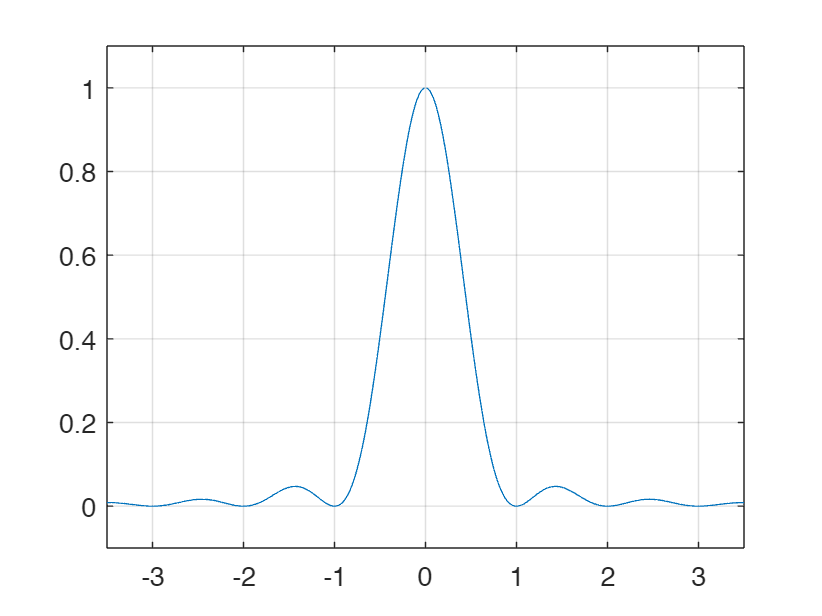

%P_sinc.m Plotting of sincA2(x) function
clc;
clear;
close all;

x=-3.5:0.01:3.5;
Sinc=sin(pi*x)./(pi*x);
plot(x,Sinc.*conj(Sinc));
axis([-3.5 3.5 -0.1 1.1]);
grid on;

## HG.m (m-file for plotting intensity patterns of Hernite-Gaussian modes)

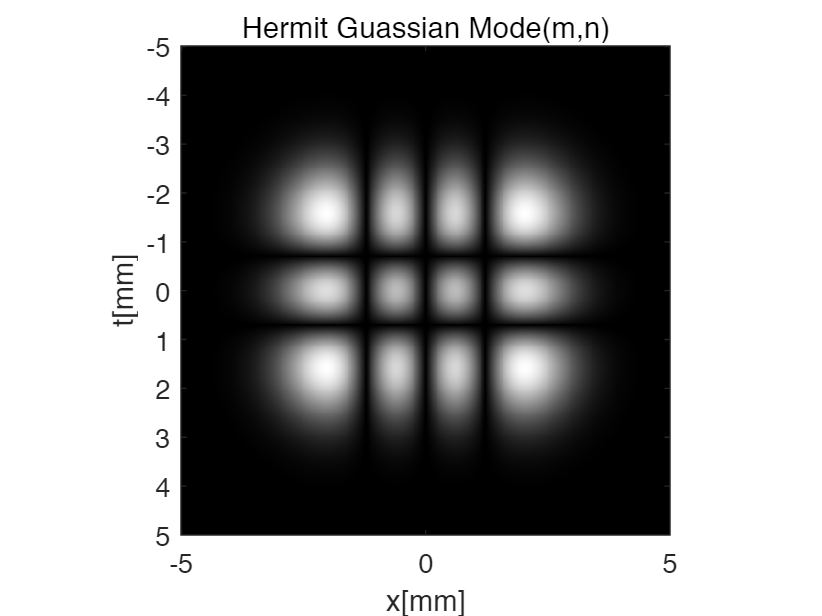

% plotting Hermit-Gaussians up to m=n=3 mode
clc;
clear;
close all;

m = input('m(between 0 to 3) = ');
n = input('n(between 0 to 3) = ');

% waist = (ko/d)^0.5 = 1 mm
ko_d = 1;
Xmin = -5;
Xmax = 5;
Step_s = 0.0001*300/(1.276*1.2);
x = Xmin:Step_s:Xmax;
y=x;

if m==0
    Hm = ones(size(x));
end
if m==1
    Hm = 2*x*ko_d;
end
if m==2
    Hm = 4*x.^2 - 2*ones(size(x));
end
if m==3
    Hm = 8*x.^3 - 12*x;
end

if n==0
    Hn = ones(size(x));
end
if n==1
    Hn = 2*x*ko_d;
end
if n==2
    Hn = 4*x.^2 - 2*ones(size(x));
end
if n==3
    Hn = 8*x.^3 - 12*x;
end

% length of consideration range
L = Xmax - Xmin;
n = size(x);
N = n(2);
for k = 1:N
    for l = 1:N
        psy(k,l) = exp(j*ko_d/2*(x(l)^2 + y(k)^2)) * Hm(l) * Hn(k) * exp(-ko_d/2*(x(l)^2+y(k)^2));
    end
end

figure(1);
image(x,y,256*abs(psy)/max(max(abs(psy))));
colormap(gray(256));
title('Hermit Guassian Mode(m,n)');
xlabel('x[mm]');
ylabel('t[mm]');
axis square;

## Gaussian_propagation.m (m-file for calculating diffracted Gaussian beam)

MATLAB example: Propagation of a Gaussian beam

初始相位为平面的高斯光束在傍轴区域的传播。

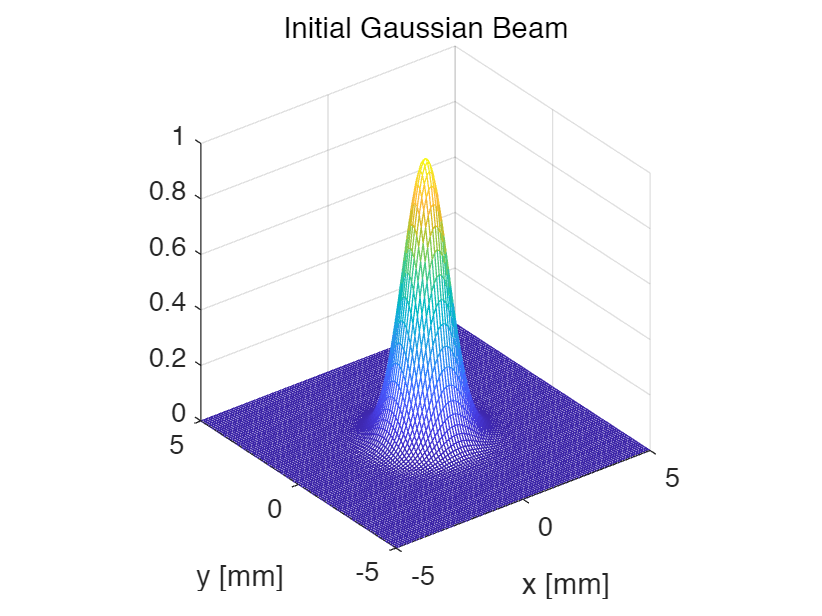

%Gaussian_propagation.m
%Simulation of diffraction of Gaussian Beam

clc;
clear;
close all;
%Gaussian Beam
%N : sampling number
N=input('Number of samples (enter from 100 to 500) = ');
L=10*10^-3;
Ld=input('wavelength of light in [micrometers] = ');
Ld=Ld*10^-6;
ko=(2*pi)/Ld;
wo=input('Waist of Gaussian Beam in [mm] = ');
wo=wo*10^-3;
z_ray=(ko*wo^2)/2*10^3;
sprintf('Rayleigh range is %f [mm]', z_ray);
z_ray=z_ray*10^-3;
z=input('Propagation length (z) in [mm] = ');
z=z*10^-3; 

% dx : step size
dx=L/N;
for n=1:N+1
    for m=1:N+1
        
        %Space axis
        x(m)=(m-1)*dx-L/2;
        y(n)=(n-1)*dx-L/2;

        % Gaussian Beam in space domain
        Gau(n,m)=exp(-(x(m)^2+y(n)^2)/(wo^2));

        %Frequency axis
        Kx(m)=(2*pi*(m-1))/(N*dx)-((2*pi*(N))/(N*dx))/2;
        Ky(n)=(2*pi*(n-1))/(N*dx)-((2*pi*(N))/(N*dx))/2;

        %Free space transfer function
        H(n,m)=exp(j/(2*ko)*z*(Kx(m)^2+Ky(n)^2));
    end
end

%Gaussian Beam in Frequency domain
FGau=fft2(Gau);
FGau=fftshift(FGau);

%Propagated Gaussian beam in Frequency domain
FGau_pro=FGau.*H;

%Peak amplitude of the initial Gaussian beam
Peak_ini=max(max(abs(Gau)));
sprintf('Initial peak amplitude is %f [mm]', Peak_ini);

%Propagated Gaussian beam in space domain
Gau_pro=ifft2(FGau_pro);
Gau_pro=Gau_pro;

%Peak amplitude of the propagated Gaussian beam
Peak_pro=max(max(abs(Gau_pro)));
sprintf('Propagated peak amplitude is %f [mm]', Peak_pro);

%Calculated Beam Width
[N M]=min(abs(x));
Gau_pro1 =Gau_pro(: ,M);
[N1 M1]= min(abs(abs(Gau_pro1)- abs( exp(-1)*Peak_pro)));
Bw=dx*abs(M1 -M)* 10^3;
sprintf('Beam width (numerical)is %f [mm]', Bw);

%Theoretical Beam Width
W=(2*z_ray)/ko*(1+(z/z_ray)^2);
W=(W^0.5)*10^3;
sprintf('Beam width (theoretical)is %f [mm]', W);

%axis in mm scale
x=x*10^3;
y=y*10^3;

figure(1);
mesh(x,y,abs(Gau));
title('Initial Gaussian Beam');
xlabel('x [mm]');
ylabel('y [mm]');
axis([min(x) max(x) min(y) max(y) 0 1]);
axis square;

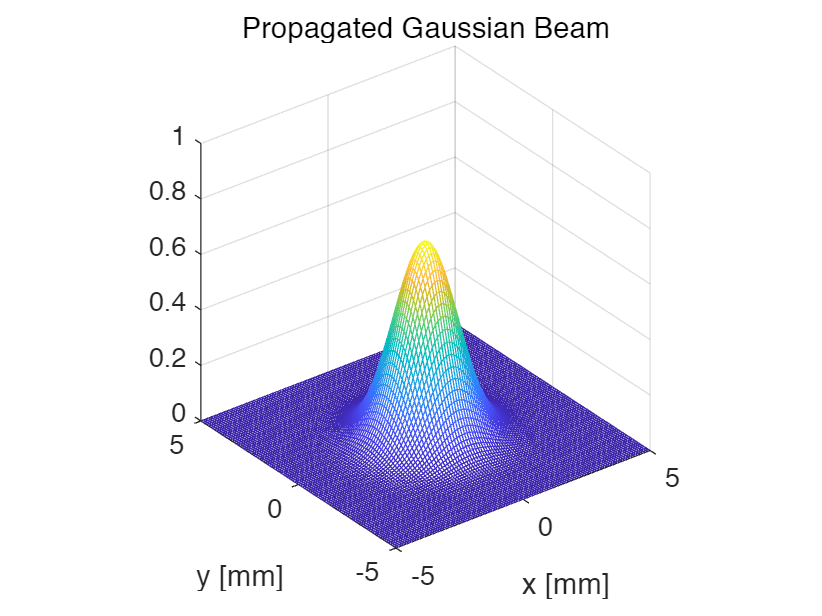


figure(2);
mesh(x,y,abs(Gau_pro));
title('Propagated Gaussian Beam');
xlabel('x [mm]');
ylabel('y [mm]');
axis([min(x) max(x) min(y) max(y) 0 1]);
axis square;

Number of samples (enter from 100 to 500) = 100

wavelength of light in [micrometers] = 0.6328

Waist of Gaussian Beam in [mm] = 1

Propagation length (z) in [mm] = 4964.590161

## BPMfocusinglens.m (m-file for the simulation of Gaussian beam focused by a lens Using BPM)

MATLAB Examples Using the Split-Step Beam Propagation Method

%BPM_focusing_lens.m
%Simulation of Gaussian Beam Focused by a Lens Using BPM

%Paramters suggested for simulation :
% Ld (light wavelength) =0.633, wo (waist)=10,
% dz(sample distance along z)=800,
% Z(total final distance away from lens) =40000,
% f(focal length)= 16000

clc;
clear;
close all;

%Gaussian Beam 
N=255;%N : sampling number
L=50*10^-3; %Display area

Ld=input('wavelength of light in [micrometers] = ');
Ld=Ld*10^-6;
ko=(2*pi)/Ld;

wo=input('Waist of Gaussian Beam in [mm] = ');
wo=wo*10^-3;

dz=input('step size of z (dz) in [mm] = ');
dz=dz*10^-3;

Z=input('destination of z in [mm] =  ');
Z=Z*10^-3;

%Focal length of Lens
f=input('Focal length of lens in [mm]= ');
f=f*10^-3;

% dx : step size
dx=L/N;

for n= 1:256
    for m=1:256
        %Space axis
        x(m)=(m-1)*dx-L/2;
        y(n)=(n-1)*dx-L/2;

        %Frequency axis
        Kx(m)=(2*pi*(m-1))/(N*dx)-((2*pi*(256-1))/(N*dx))/2;
        Ky(n)=(2*pi*(n-1))/(N*dx)-((2*pi*(256-1))/(N*dx))/2;
    end
end

[X,Y]=meshgrid(x,y);
[KX, KY]=meshgrid(Kx,Kx);

%Gaussian Beam in space domain
Gau_ini=(1/(wo*pi^0.5))*exp(-(X.^2+Y.^2)./(wo^2));

%Energy of the initial Gaussian beam
Energy_ini=dx*dx*sum(sum(abs(Gau_ini).^2))

Energy_ini = 0.5000


%Lens Equation
L=exp(j*ko/(2*f)*(X^2+Y^2));

%Gaussian Beam passed through the lens
Gau_ini=Gau_ini.*L;

%Free space transfer function of propagation
H=exp(j/(2*ko)*dz*(KX.^2+KY.^2));

%Iterative Loop
Gau=Gau_ini;
n1=0;
for z=0:dz:Z
    n1=n1+1; 
    Zp(n1)=z+dz; 
    %Gaussian Beam in Frequency domain 
    FGau=fft2(Gau); 
    %Propagated Gaussian beam in Frequency domain
    FGau=FGau.*fftshift(H); 
    %Propagated Gaussian beam in space domain 
    Gau=ifft2(FGau); 
    %Step propagation through medium 
    Gau_pro(:,n1)=Gau(:,127); 
end

%Energy of the final propagated Gaussian beam, 
%to check conservation of energy 
Energy_pro=dx*dx*sum(sum(abs(Gau).^2)) 

Energy_pro = 0.5000

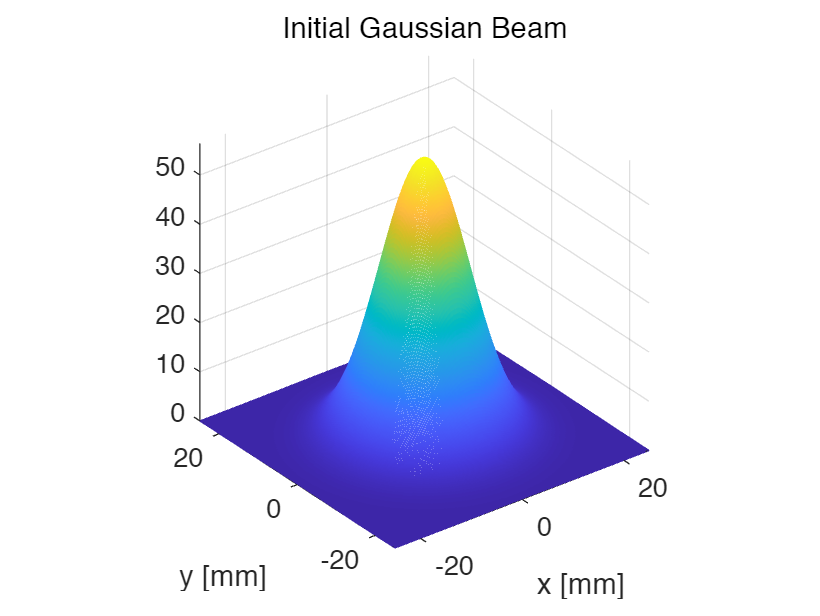


%axis in mm scale
x=x*10^3; 
y=y*10^3; 
Zp=Zp*10^3; 
MAX1=max(max(abs(Gau_ini))); 
MAX2=max(max(abs(Gau))); 
MAX=max([MAX1 MAX2]); 

figure(1); 
mesh(x,y,abs(Gau_ini));
title('Initial Gaussian Beam');
xlabel('x [mm]');
ylabel('y [mm]');
axis([min(x) max(x) min(y) max(y) 0 MAX]);
axis square;

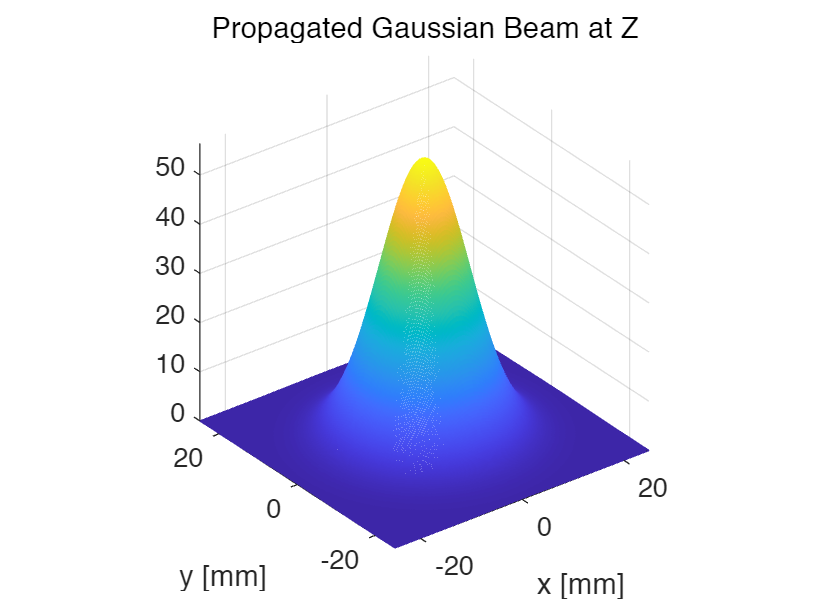


figure(2); 
mesh(x,y,abs(Gau));
title('Propagated Gaussian Beam at Z');
xlabel('x [mm]');
ylabel('y [mm]');
axis([min(x) max(x) min(y) max(y) 0 MAX]);
axis square;

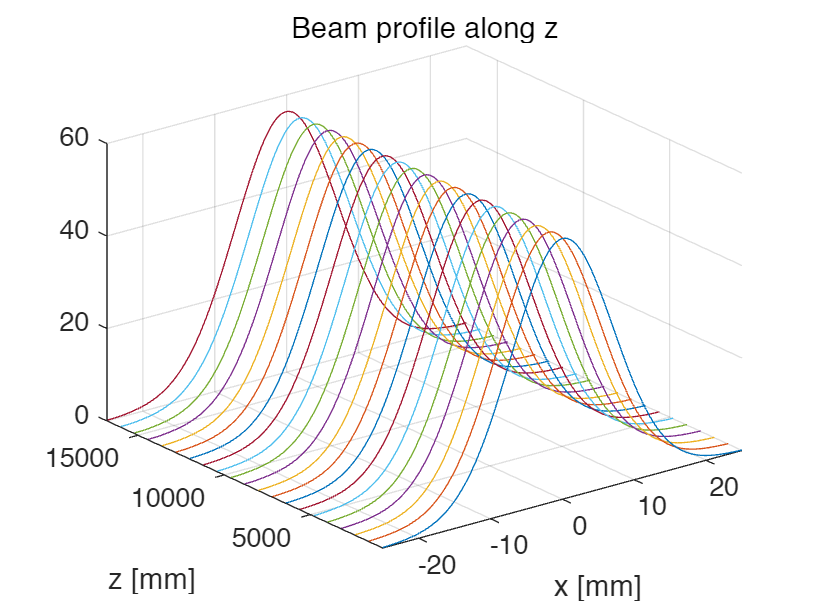


figure(3);
for k=1:n1 
    plot3(x',Zp(k)*ones(size(x')),abs(Gau_pro(:,k)));
    hold on;
end
axis([min(x) max(x) min(Zp) max(Zp)]);
grid on;
title('Beam profile along z');
xlabel('x [mm]');
ylabel('z [mm]');
hold off;

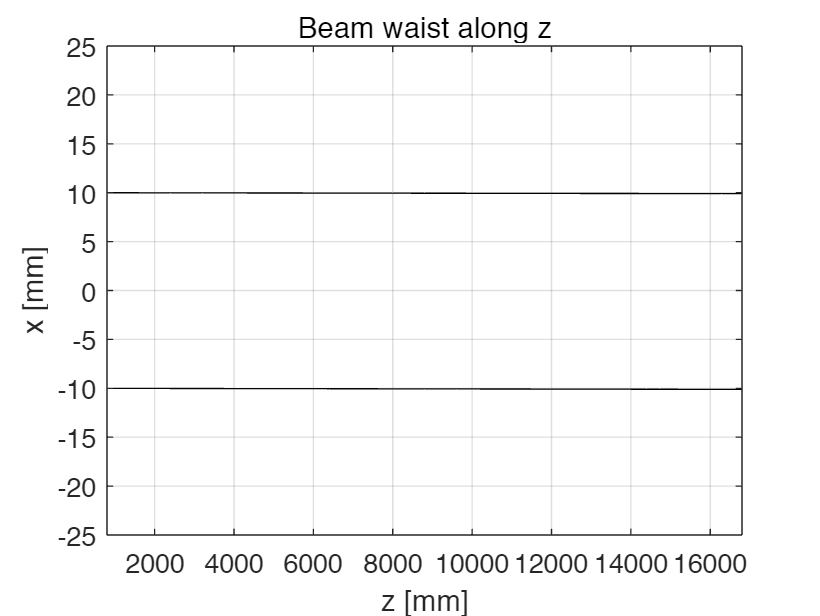


figure(4);
A=max(abs(Gau_pro));
B=diag(1./A);
N_Gau_pro=abs(Gau_pro)*B; 
contour(Zp,x,N_Gau_pro, [exp(-1) exp(-1)], 'k');
grid on;
title('Beam waist along z');
xlabel('z [mm]');
ylabel('x [mm]');

## BPM_sq_law_medium.m (m-file for the simulation of Gaussian beam propagating in a square-law medium using BPM)

%BPM_sq_law_medium.m 
%Simulation of Gaussian Beam Propagation in a Square-Law Medium Using BPM 
%This program demonstrates periodically focusing and defocusing 

% Suggested simulation parameters 

% For initially converging situation: 
% L=20 
% Ld=0.633; 
% wo=5; 
% dz=2000 
% Z=80000

% For initially diverging situation: 
% L=15 
% Ld=0.633;
% wo=l; 
% dz=2000
% Z=80000 

clc;
clear;
close all;

n0=1.5; 
n2=0.01; % with unit of (meter)^-2

%Gaussian Beam 
%N : sampling number 
N=255; 

L=input('Length of back ground in [mm] = '); 
L=L*10^-3; 

Ld=input('Incident wavelength of light in [micrometers] = '); 
Ld=(Ld/n0)*10^-6; 
ko=(2*pi)/Ld; %wavenumber in nO 

wo=input('Waist of Gaussian Beam in [mm] = '); 
wo=wo*10^-3; 

dz=input('step size of z (dz) in [mm] = '); 
dz=dz*10^-3; 

Z=input('destination of z in [mm] = '); 
Z=Z*10^-3; 

% dx : step size 
dx=L/N;

for n=1:256 
    for m=1:256 
        %Space axis 
        x(m)=(m-1)*dx-L/2; 
        y(n)=(n-1)*dx-L/2; 
        
        %Frequency axis 
        Kx(m)=(2*pi*(m-1))/(N*dx)-((2*pi*(256-1))/(N*dx))/2; 
        Ky(n)=(2*pi*(n-1))/(N*dx)-((2*pi*(256-1))/(N*dx))/2; 
    end 
end

[X,Y]=meshgrid(x,y); 
[KX, KY]=meshgrid(Kx,Kx); 

%Gaussian Beam in space domain 
Gau_ini=(1/(wo*pi^0.5))*exp(-(X.^2+Y.^2)./(wo^2)); 

%Energy of the initial Gaussian beam 
Energy_ini=dx*dx*sum(sum(abs(Gau_ini).^2)) 

Energy_ini = 0.4999


%Free space transfer function of step propagation 
H=exp(j/(2*ko)*dz*(KX.^2+KY.^2)); 

%S operator according to index profile of medium 
S=-j*(-n2/(2*n0*n0)*(X.^2+Y.^2))*ko;


%Iterative Loop
Gau=Gau_ini;
n1=0;
for z=0:dz:Z
    n1=n1+1; 
    Zp(n1)=z+dz; 
    %Gaussian Beam in Frequency domain 
    FGau=fft2(Gau); 
    %Propagated Gaussian beam in Frequency domain
    FGau=FGau.*fftshift(H); 
    %Propagated Gaussian beam in space domain 
    Gau=ifft2(FGau); 
    %Step propagation through medium 
    Gau=Gau.*exp(S.*dz);
    Gau_pro(:,n1)=Gau(:,127); 
end

%Energy of the final propagated Gaussian beam, 
%to check conservation of energy 
Energy_pro=dx*dx*sum(sum(abs(Gau).^2)) 

Energy_pro = 0.4999

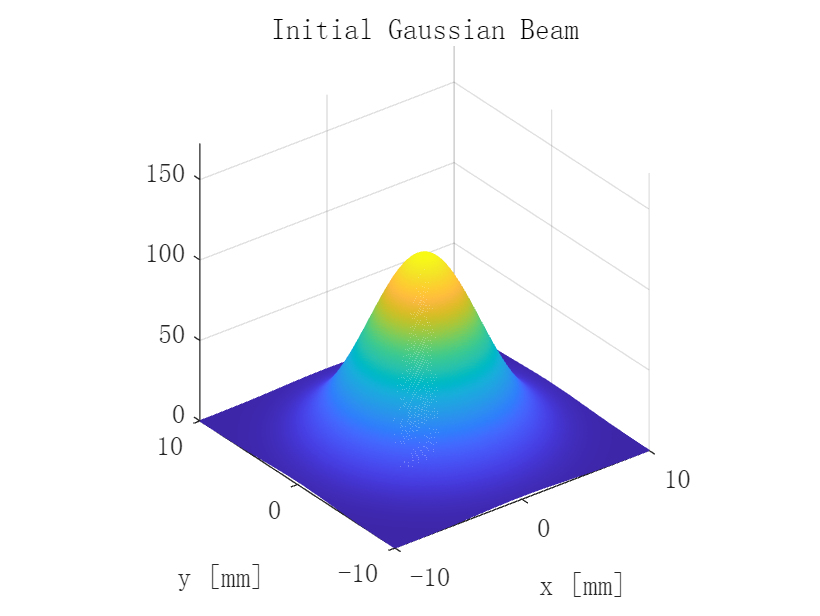


%axis in mm scale
x=x*10^3; 
y=y*10^3; 
Zp=Zp*10^3; 
MAX1=max(max(abs(Gau_ini))); 
MAX2=max(max(abs(Gau))); 
MAX=max([MAX1 MAX2]); 

figure(1); 
mesh(x,y,abs(Gau_ini));
title('Initial Gaussian Beam');
xlabel('x [mm]');
ylabel('y [mm]');
axis([min(x) max(x) min(y) max(y) 0 MAX]);
axis square;

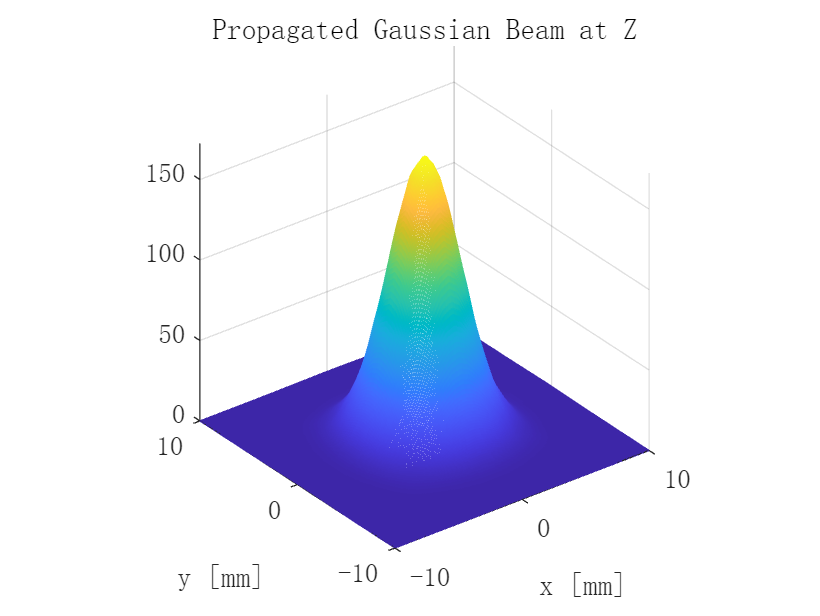


figure(2); 
mesh(x,y,abs(Gau));
title('Propagated Gaussian Beam at Z');
xlabel('x [mm]');
ylabel('y [mm]');
axis([min(x) max(x) min(y) max(y) 0 MAX]);
axis square;

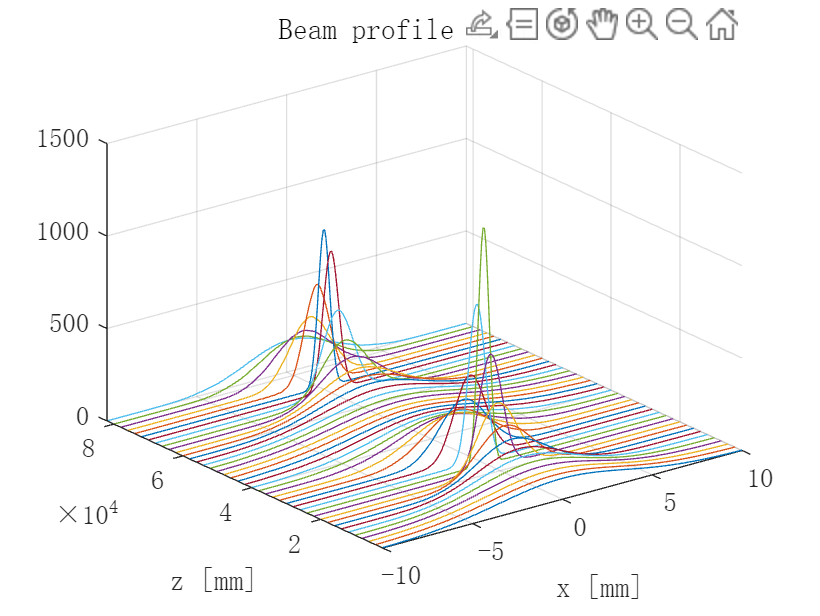


figure(3);
for k=1:n1 
    plot3(x',Zp(k)*ones(size(x')),abs(Gau_pro(:,k)));
    hold on;
end
grid on;
axis([min(x) max(x) min(Zp) max(Zp)]);
title('Beam profile along z');
xlabel('x [mm]');
ylabel('z [mm]');
hold off;


w00=(2/((ko/n0)*(n2^0.5)))^0.5; %fundamental mode width 
w00=w00*10^3; 
sprintf('w00, fundamental mode width in [mm] %f' , w00)

ans = 'w00, fundamental mode width in [mm] 1.419472'

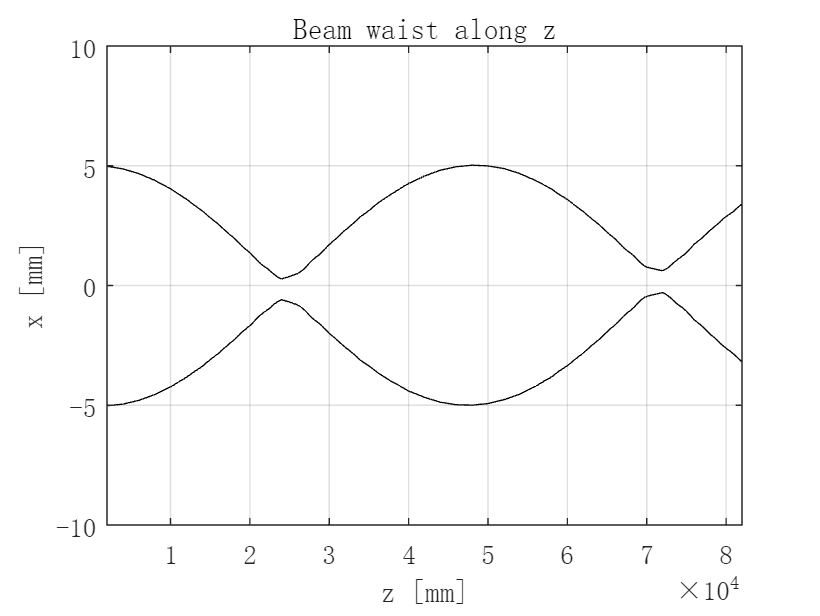


figure(4);
A=max(abs(Gau_pro));
B=diag(1./A);
N_Gau_pro=abs(Gau_pro)*B; 
contour(Zp,x,N_Gau_pro, [exp(-1) exp(-1)], 'k');
grid on;
title('Beam waist along z');
xlabel('z [mm]');
ylabel('x [mm]');


zm=pi*n0/((n2^0.5));%modulation period
zm=zm*10^3;
sprintf('zm, modulation period in [mm] %f',zm);

## IndexEllipsoid.m (m-file for plotting Eq. (5.6-1)).

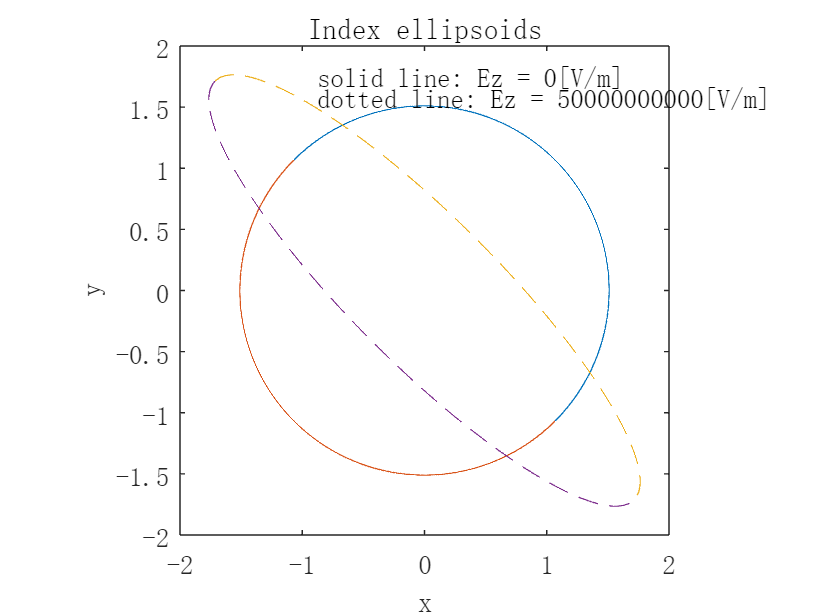

clc;
clear;
close all;

no=1.51;
%no is the refractive index of the ordinary axis of KDP
r63=10.6*10^-12; %Electro-optic Coefficient (r63)of KDP
E=input('Applied Electric Field [V/m] = '); 
%suggested value is 0.5*10^11

for n = 1:2
    if n==1
        Ez=0;
    end
    if n==2
        Ez=E;
    end
    nx_p = no + (no^3)/2*r63*Ez;%principal refractive index along x', see Eq. (5.6-4)
    ny_p = no - (no^3)/2*r63*Ez;%principal refractive index along y'

    %Calculate the index ellipsoid in the presence of applied electric field 
    x_p=-nx_p:nx_p/1000:nx_p; %Range of x' 
    y1_p=ny_p*(ones(size(x_p))-(x_p./nx_p).^2).^0.5; %Corresponding positive y' 
    y2_p=-ny_p*(ones(size(x_p))-(x_p./nx_p).^2).^0.5;%Corresponding negative y'

    %Transform (x',y') to the (x,y) 
    %x11 and x12 are the x's 
    %y11 and y12 are the y's
    x11 = 1/(2^0.5)*(x_p + y1_p);
    y11 = -1/(2^0.5)*(x_p - y1_p);
    x12 = 1/(2^0.5)*(x_p + y2_p);
    y12 = -1/(2^0.5)*(x_p - y2_p);

    if n==1
        figure(1);
        plot(x11,real(y11),'-');
        hold on;
        plot(x12,real(y12),'-');
    end

    if n==2
        plot(x11,real(y11),'--');
        hold on;
        plot(x12,real(y12),'--');
    end
end

text(-max(x11)*0.5,max(y11),['solid line: Ez = ',num2str(0),'[V/m]']);
text(-max(x11)*0.5,max(y11)*0.9,['dotted line: Ez = ',num2str(E),'[V/m]']);
axis square;
hold off;
xlabel('x');
ylabel('y');
title('Index ellipsoids');